## **Exercise 2, week 2 (Flow System Modelling)**

Consider a continuous flow system consisting of 6 equal compartments in series with backflow. The backflow ratio is $f=0.1$ for all compartments, except between compartments 1 and 2, where $f=0.3$. The average residence time has been normalized to 1.

**Tasks**:

- **a.** Use a simulation to compute the residence time distribution.

- **b.** Compare the result with the case without backflow. Is the backflow response showing a certain skewness? Explain your answer.

- **c.** Compute the central moments $\mu_1$�, $\mu_2$�, and $\mu_3$� for both models.

- **d.** Compute the flow rate matrix as part of a state-space representation for the case with backflow (refer to Section 2.3 of the lecture notes). Show that the flow rate matrix is positive definite and demonstrate stability of the flow system, for example, by computing the eigenvalues of the flow rate matrix.

close all
clear
clc

% Given parameters
f = 0.1;   % Backflow ratio for compartments
f_12 = 0.3; % Backflow ratio for compartments 1 and 2
v = 1;     % Volume, assuming L/v = 1
N = 6;     % Number of compartments = 6
L = 1;     % Length, assuming L/v = 1

% Calculate α, β, and γ according to lecture notes page 59
alpha = (1 + f) * v * N / L;
beta = (1 + 2 * f) * v * N / L;
gamma = f * v * N / L;

% Calculate α, β, and γ for compartment 1 and 2
alpha_12 = (1 + f_12) * v * N / L;
beta_12 = (1 + 2 * f_12) * v * N / L;
gamma_12 = f_12 * v * N / L;

Reffering to the formula to model N compartments with backflow we have (sections 2.3.2): 


$$\[
\frac{d}{dt} c_k(t) = \frac{(1 + f) v N}{L} c_{k-1}(t) + \frac{f v N}{L} c_{k+1}(t) - \frac{(1 + 2f) v N}{L} c_k(t)
\]$$


In order to model this in Simlulink, we use the State Space block. We know that the state space form looks like this: 


$$\[
\dot{x}(t) = A x(t) + B u(t)
\]

\[
y(t) = C x(t) + D u(t)
\]$$


Again using the lecture notes we can define turn the equasion in 2.3.2 into state space form: 

 (just see lecture notes, my latex code is not working for some reason)

Now we can define A, B, C and D like this:

% TODO: I'm not sure if this is the right way to apply the new f_12

A_bf = [
    -alpha_12, gamma_12, 0, 0, 0, 0;
    alpha_12, -beta_12, gamma, 0, 0, 0;
    0, alpha, -beta, gamma, 0, 0;
    0, 0, alpha, -beta, gamma, 0;
    0, 0, 0, alpha, -beta, gamma;
    0, 0, 0, 0, alpha, -alpha
];

B_bf = [
    alpha - gamma;
    0;
    0;
    0;
    0;
    0
];

C_bf = [0, 0, 0, 0, 0, 1]; 
D_bf = 0;

We use simlunk to model 6 compartments and use the results to plot the residence time 

cin = 1 % this is out input, it's 1 for simplicity

cin = 1

for the case without backflow we can use equasion 2.50: 


$$\frac{d}{dt} c_{k+1}(t) = \frac{v}{N L} \left[ c_k(t) - c_{k+1}(t) \right], \quad k = 0, 1, \dots, N-1$$


Again, we can turn this into state space and define new variable for A, B, C and D:

% Define the matrix A, B, C and D for case without backflow
A_nobf = zeros(N);
B_nobf = zeros(N, 1);
C_nobf = zeros(1, N);
D_nobf = 0;

% Set elements of A accodring to lecture notes
for i = 1:N
    if i == 1
        A_nobf(i, i) = -v * N / L;
        A_nobf(i, i+1) = 0;
    elseif i == N
        A_nobf(i, i) = -v * N / L;
        A_nobf(i, i-1) = v * N / L;
    else
        A_nobf(i, i) = -v * N / L;
        A_nobf(i, i-1) = v * N / L;
        A_nobf(i, i+1) = 0;
    end
end

% Set the first element of B
B_nobf(1) = v * N / L;

% Set the last element to 1
C_nobf(N) = 1; 


Now we can run the simulation and plot the residence distrbution for N= 6 compartments with and without backflow:

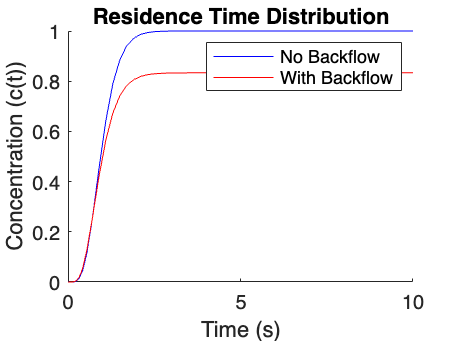

% Run the simulation and store the output
out = sim('exercise2_model');

% Access the output signal for No Backflow
simout_data_nobf = out.simout_nobf;

% Extract the time and data from the timeseries object (No Backflow)
time_nobf = simout_data_nobf.Time;  % Time vector (No Backflow)
output_data_nobf = simout_data_nobf.Data;  % The actual data (No Backflow)

% Access the output signal for Backflow
simout_data_bf = out.simout_bf;

% Extract the time and data from the timeseries object (Backflow)
time_bf = simout_data_bf.Time;  % Time vector (Backflow)
output_data_bf = simout_data_bf.Data;  % The actual data (Backflow)

% Plot both Residence Time Distributions (No Backflow and Backflow) in one figure
figure;
hold on;
plot(time_nobf, output_data_nobf, 'b', 'DisplayName', 'No Backflow');  % Blue for No Backflow
plot(time_bf, output_data_bf, 'r', 'DisplayName', 'With Backflow');  % Red for Backflow
hold off;

% Add labels, title, and legend
xlabel('Time (s)');
ylabel('Concentration (c(t))');
title('Residence Time Distribution');
legend('show');

To Calculate the central moments (mean, variance and skewness) we can use the formulas: 

% Central moments for No Backflow
mu1_nobf = sum(time_nobf .* output_data_nobf) / sum(output_data_nobf);
mu2_nobf = sum((time_nobf - mu1_nobf).^2 .* output_data_nobf) / sum(output_data_nobf);
mu3_nobf = sum((time_nobf - mu1_nobf).^3 .* output_data_nobf) / sum(output_data_nobf);

% Central moments for Backflow
mu1_bf = sum(time_bf .* output_data_bf) / sum(output_data_bf);
mu2_bf = sum((time_bf - mu1_bf).^2 .* output_data_bf) / sum(output_data_bf);
mu3_bf = sum((time_bf - mu1_bf).^3 .* output_data_bf) / sum(output_data_bf);

% Display the central moments
disp('Central Moments for No Backflow:');

Central Moments for No Backflow:


disp(['Mean (mu1): ', num2str(mu1_nobf)]);

Mean (mu1): 5.5788


disp(['Variance (mu2): ', num2str(mu2_nobf)]);

Variance (mu2): 7.1478


disp(['Skewness (mu3): ', num2str(mu3_nobf)]);

Skewness (mu3): -0.48716



disp('Central Moments for Backflow:');

Central Moments for Backflow:


disp(['Mean (mu1): ', num2str(mu1_bf)]);

Mean (mu1): 5.556


disp(['Variance (mu2): ', num2str(mu2_bf)]);

Variance (mu2): 7.225


disp(['Skewness (mu3): ', num2str(mu3_bf)]);

Skewness (mu3): -0.52982


For the last part, we use the A_bf matrix we used to compute eigen values: 

% Display the Flow Rate Matrix A
disp('Flow Rate Matrix A:');

Flow Rate Matrix A:


disp(A_bf);

   -7.8000    1.8000         0         0         0         0
    7.8000   -9.6000    0.6000         0         0         0
         0    6.6000   -7.2000    0.6000         0         0
         0         0    6.6000   -7.2000    0.6000         0
         0         0         0    6.6000   -7.2000    0.6000
         0         0         0         0    6.6000   -6.6000




% Check if the matrix is positive definite
eigenvalues_A = eig(A_bf); % Compute eigenvalues of the matrix

% Display the eigenvalues
disp('Eigenvalues of A:');

Eigenvalues of A:


disp(eigenvalues_A);

  -13.0529
  -10.2497
   -8.1884
   -3.5964
   -6.0189
   -4.4936




% Check if all eigenvalues are positive (positive definite check)
is_positive_definite = all(eigenvalues_A > 0);

% Display result for positive definiteness
if is_positive_definite
    disp('The matrix A is positive definite.');
else
    disp('The matrix A is NOT positive definite.');
end

The matrix A is NOT positive definite.



% Check for stability (for stability, eigenvalues should have negative real parts)
is_stable = all(real(eigenvalues_A) < 0);

% Display result for stability
if is_stable
    disp('The system is stable.');
else
    disp('The system is NOT stable.');
end

The system is stable.
